# Diseño controlador H-infinito / Sensibilidad Mixta

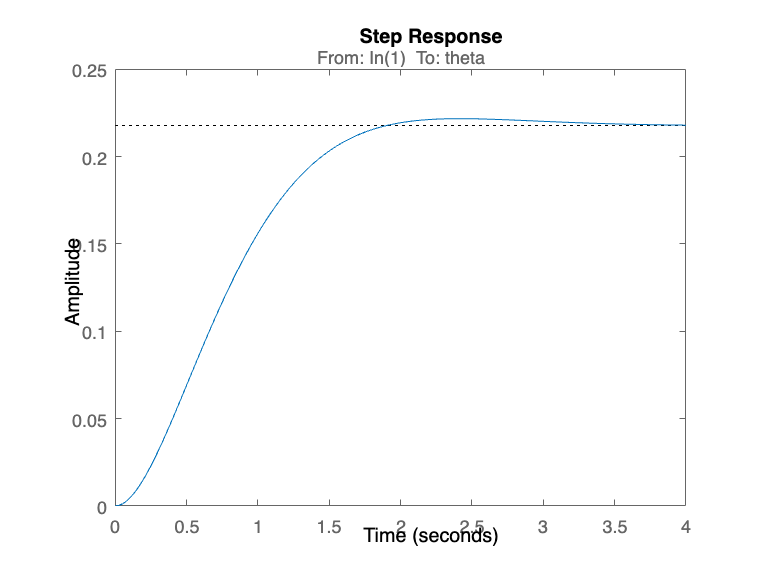

step(Gss); %% Lazo abierto de planta

Definición de las prestaciones: 

- Seguimiento de Referencia Perfecto (ep = 0) 

- Accion de Control entre (0 < u < 100) [ % PWM ]

- Menor tiempo posible (Mayor ancho de banda) 

- Rechazo a perturbaciones 

Definición de señales 

- ***El controlador recibe error en radianes y lo convierte a Porcentaje de PWM % ***

## Definición de Filtros de Ponderación

- $S$ -> Sensibilidad del sistema 

- KS -> Accion de control 

- T -> Sensibilidad Complementaria 


$$T+S=1$$
 

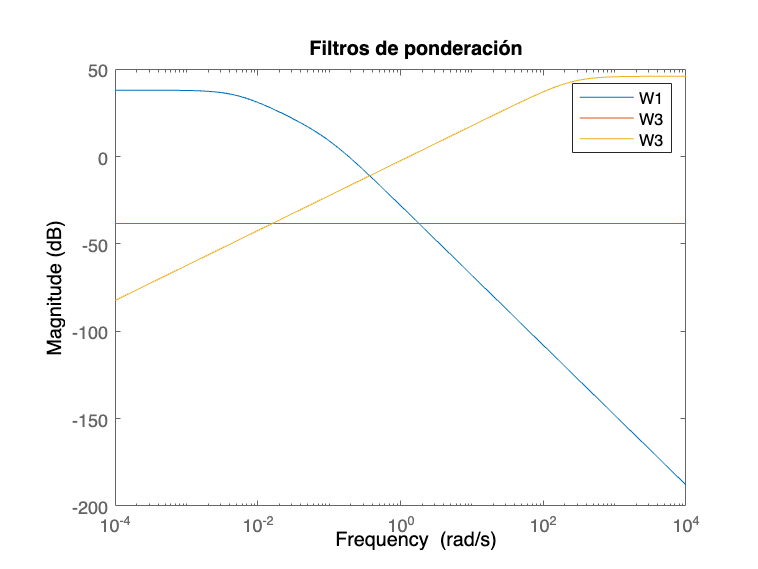

% Definición de filtros 

s = tf('s'); 
W1 = makeweight(80, 0.4, 1e-6) * 1/(s/0.1 + 1);       %% Sensibilidad 
W2 = ss(1/50 * deg2rad(35));      %% Acción de Control  
W3 = makeweight(1e-6,1.3, 200);      %% Sensibilidad Complementaria
% Grafica de filtros 
bodemag(W1, W2, W3);
legend("W1", "W3", "W3"); 
title("Filtros de ponderación"); 

[K, CL, GAM] = mixsyn(Gss, W1, W2, W3); % Solucion problema H-infinito
GAM

GAM = 0.3480

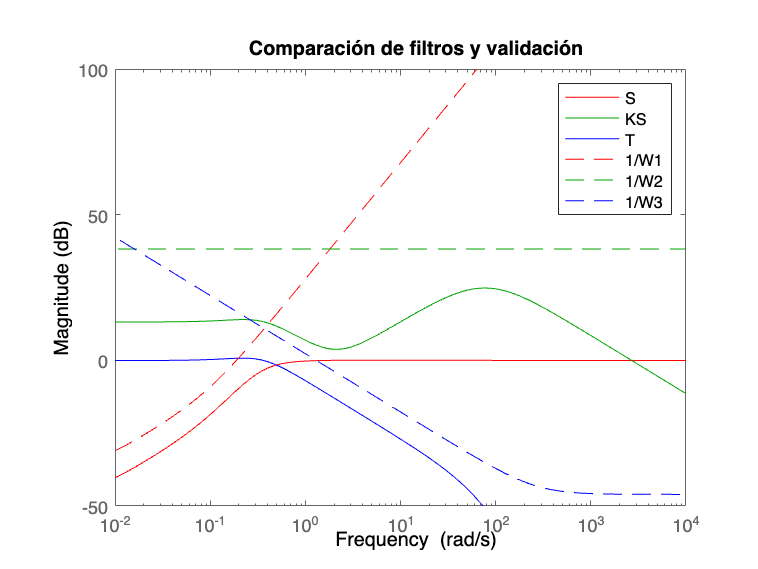

% Validación de filtros y H infinito 
S = feedback(1, K * G);
KS = K * S; 
T = 1 - S; 

% Graficas 
bodemag(S, "r-", KS, "g-", T, "b-"); hold on; 
bodemag(1/W1, "r--", 1/W2, "g--", 1/W3, 'b--'); hold off;
title("Comparación de filtros y validación"); 
legend("S", "KS", "T", "1/W1", "1/W2", "1/W3")
axis([1e-2 10e3, -50, 100]); 

## Respuesta de lazo cerrado

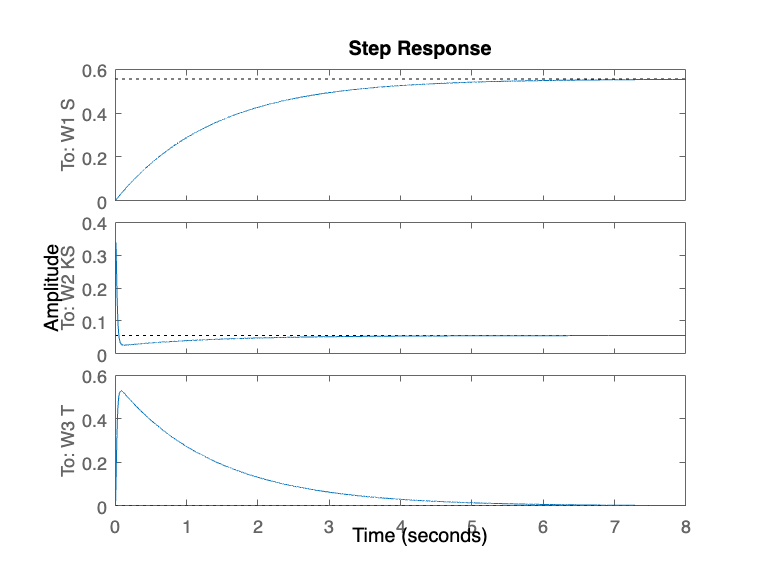

% MAtriz de transferencia aumentada
CL.OutputName = {'W1 S', 'W2 KS', 'W3 T'}; 
step(CL); 

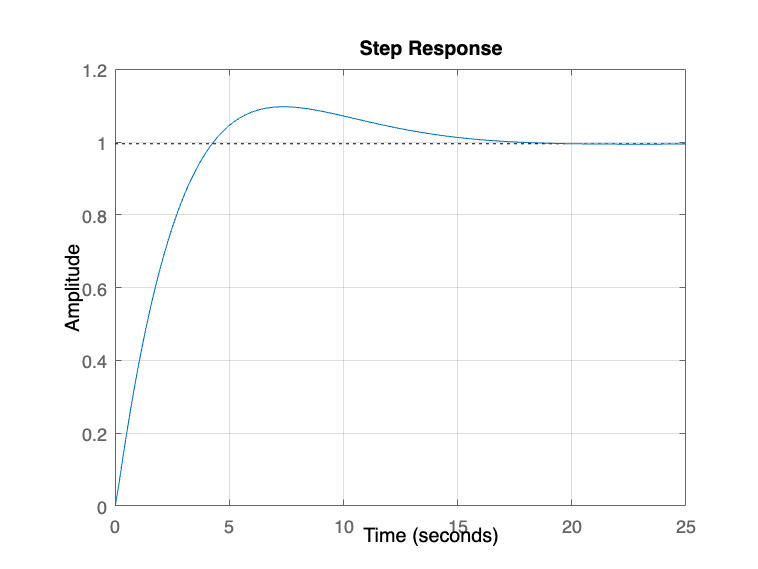

OL = series(K, G); 
T = feedback(OL, 1); 
U = feedback(K, G); 


%% Respuesta directa 
step(T); 
bandwidth(T); grid on; 

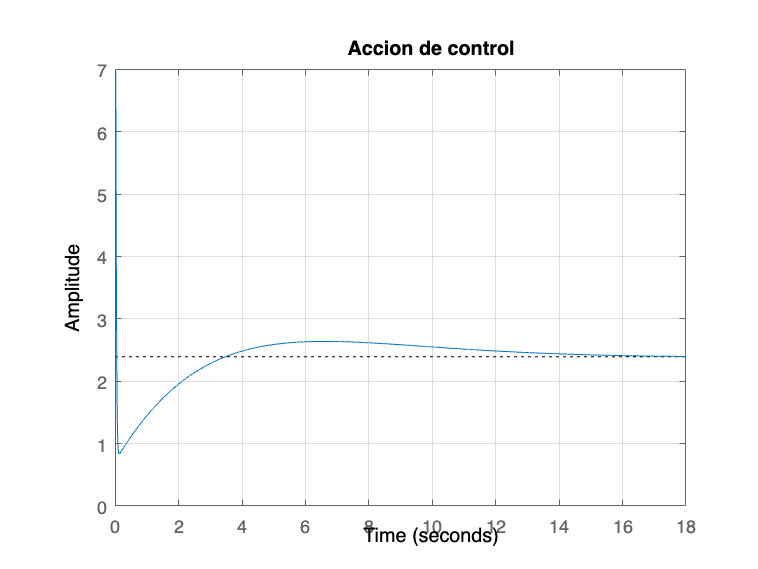


% Respuesta de accion de control
step(pi/6 * U);  
title("Accion de control"); grid on; 

% Función de transferencia; 
size(K); 

State-space model with 1 outputs, 1 inputs, and 4 states.


Ktf = tf(K); 

## Implementacion en arduino

Ts = 2.5e-3;  % Tiempo de muestreo

HinfDiscrete = c2d(K, Ts, 'tustin')

HinfDiscrete =
 
  A = 
               x1          x2          x3          x4          x5
   x1           1   0.0004999  -1.332e-17   7.993e-17   3.057e-18
   x2           0      0.9998           0           0           0
   x3    0.008399    0.006601      0.5099      0.4789   0.0005039
   x4     0.03478     0.02733    0.001954      0.9828    0.002087
   x5       27.82       21.87       1.563      -13.77      0.6692
 
  B = 
              u1
   x1  1.562e-07
   x2  0.0006249
   x3  2.063e-06
   x4  8.541e-06
   x5   0.006833
 
  C = 
              x1         x2         x3         x4         x5
   y1  1.147e+04       9012      644.3      -5671     -132.9
 
  D = 
          u1
   y1  2.816
 
Sample time: 0.0025 seconds
Discrete-time state-space model.



save("controllers/Hinf/Hinf.mat", "HinfDiscrete"); 

## Revision en discreto

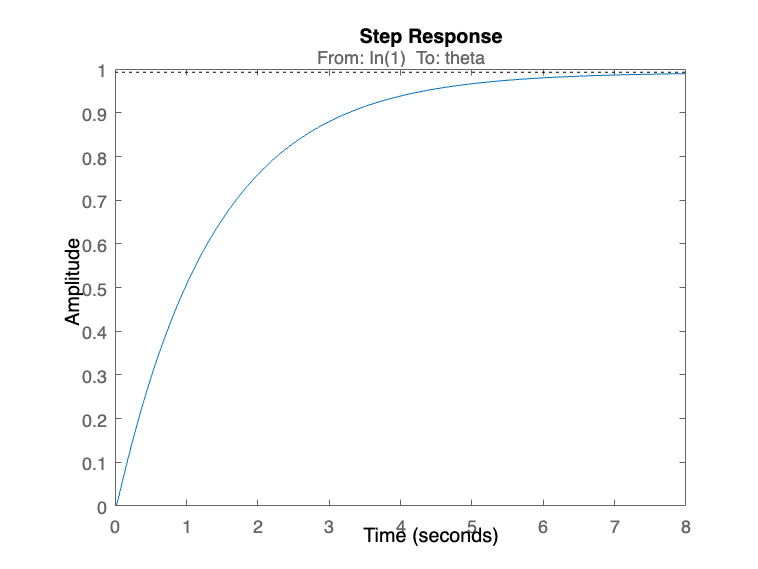

Gdiscrete = c2d(Gss, Ts, 'tustin'); 

Tdiscrete = feedback(series(HinfDiscrete, Gdiscrete), 1); 
step(Tdiscrete)